# 10.3 Optimal Control of Pitch/Travel with Feedback (LQ)

## **Load and extract data**

**Load simulink data from MAT-file**

% u_values = load("data/u_valueslab1.mat");
x_values = load("data/x_valueslab10.mat");
x_values_opt = X_opt.data;
tmpU = U_opt.data;
% u_data = u_values.data;
x_data = x_values.data;

**Get U states**

% u_time = u_data(1, :);
% u_star = u_data(2, :);
% u_ref = u_data(3, :);

**Get measured X states**

x_time = x_data(1, :);
x_travel = x_data(2, :);
x_travel_rate = x_data(3, :);
x_pitch = x_data(4, :);
x_pitch_rate = x_data(5, :);

**Get optimal X states**

x_travel_opt = x_values_opt(:, 1);
x_travel_rate_opt = x_values_opt(:, 2);
x_pitch_opt = x_values_opt(:, 3);
x_pitch_rate_opt = x_values_opt(:, 4);

## **Vizualization**

**U* vs U**

figure();

subplot(5, 1, 1);
hold on
grid on
plot(x_time, tmpU, "linewidth", 2, "linestyle","--");
% plot(u_time, u_ref, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('u*')
hold off
title("Input")
% saveas(gcf, "plots/compare_input.eps")

**Pitch* vs Pitch**


subplot(5, 1, 2);
hold on
grid on
plot(x_time, x_pitch_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_pitch, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$p^{*}$', 'p', "Interpreter", "latex")
hold off
title("Pitch")
% saveas(gcf, "plots/compare_pitch.eps")


subplot(5, 1, 3);
hold on
grid on
plot(x_time, x_pitch_rate_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_pitch_rate, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$\dot{p*}$', '$\dot{p}$', "Interpreter", "latex") 
hold off
title("Pitch rate")
% saveas(gcf, "plots/compare_pitch.eps")

**Travel* vs Travel**

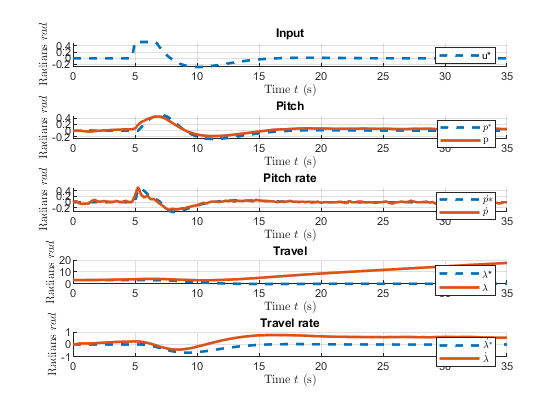


subplot(5, 1, 4);
hold on
grid on
plot(x_time, x_travel_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_travel, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('\lambda*', '\lambda') 
hold off
title("Travel")

subplot(5, 1, 5);
hold on
grid on
plot(x_time, x_travel_rate_opt, "linewidth", 2,"linestyle","--");
plot(x_time, x_travel_rate, "linewidth", 2);
xlabel("Time $t$ (s)","Interpreter", "latex")
ylabel("Radians $rad$" , "Interpreter", "latex")
legend('$\dot{\lambda^{*}}$', '$\dot{\lambda}$',"Interpreter", "latex")
hold off
title("Travel rate")


saveas(gcf, "plots/lab3_sim_lab2p10.eps")